## Design PID via root locus:

Initialize 's' as tf variable:

s=tf('s');

**Insert Plant transfer function:**

Gp = (s+1)/(s^ 4+9*s^3+26*s^2+24*s)


Gp =
 
             s + 1
  ---------------------------
  s^4 + 9 s^3 + 26 s^2 + 24 s
 
Continuous-time transfer function.



**Insert PI controller transfer function (if none insert 1):**

GcPI=(s+0.1)/s


GcPI =
 
  s + 0.1
  -------
     s
 
Continuous-time transfer function.



**Insert the design point:**

design=-1.56+1i*2.08

design = -1.5600 + 2.0800i

The uncompensated open loop response:

Uncompensated_Open=Gp*GcPI


Uncompensated_Open =
 
        s^2 + 1.1 s + 0.1
  -----------------------------
  s^5 + 9 s^4 + 26 s^3 + 24 s^2
 
Continuous-time transfer function.



Zeros:

z=zero(Uncompensated_Open)

z =    -1.0000
   -0.1000


Poles:

p=pole(Uncompensated_Open)

p =          0
         0
   -4.0000
   -3.0000
   -2.0000


The pole plot:

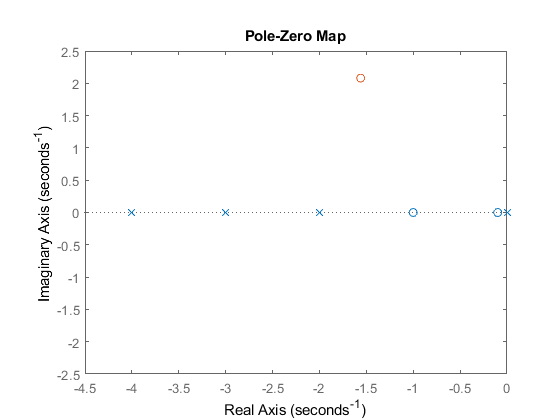

pzplot(Uncompensated_Open)
hold on
pzplot(s-design)
hold off

Get angles for zeros:

for n=1:length(z)
    z_ang(n)=angle(design-z(n))*180/pi
end

z_ang =   105.0685  125.0659


z_ang =   105.0685  125.0659


Get angles for poles:

for n=1:length(p)
    p_ang(n)= angle(design -p(n))*180/pi
end

p_ang =   126.8699 -174.1020  112.0021  119.3935


p_ang =   126.8699  126.8699  112.0021  119.3935


p_ang =   126.8699  126.8699   40.4462  119.3935


p_ang =   126.8699  126.8699   40.4462   55.3048


p_ang =   126.8699  126.8699   40.4462   55.3048   78.0558


Zeros total angle:

z_total=sum(z_ang)

z_total = 230.1344

Pole total angle:

p_total=sum(p_ang)

p_total = 427.5467


$$$$
\sum \text { zero angles }-\sum \text { pole angles }=-180^{\circ}
$$$$


PD zero angle:

Zpd=180+p_total-z_total

Zpd = 377.4123

PD zero:


$$$$\frac{imag(designpoint)}{tan(Zpd_{angle})}-real(designpoint)=Zc$$


Zc=(imag(design))/(tan(deg2rad(z1)))-real(design)

Undefined function or variable 'z1'.

Gc(s) without Kc:

Gc=GcPI*(s+Zc)

Get the value of Kc for the controller:


$$$$
G_{c}(s)=\frac{K_{c}(s+z_{lag})(s+z_{lead})}{s}
$$$$



$$$$
K_{c}=\left.\frac{1}{\left|G_{p}(s) G_{c w k}(s)\right|}\right|_{s=design}
$$$$


[NumGp,DenGp] = tfdata(Gp,'v');
[NumGc,DenGc] = tfdata(Gc,'v');
syms x
Gp_x=vpa(poly2sym((NumGp),x)/poly2sym((DenGp),x))
Gc_x=vpa(poly2sym(NumGc,x)/poly2sym(DenGc,x))
Kc=1/(abs(Gc_x*Gp_x))
x=design;
Kc=subs(Kc);
gain=vpa(Kc)

Final open loop times with gain (add gain manually from answer above):

Gopen=Gc*Gp*12.69227

Final closed loop TF:

Gclosed=feedback(Gopen,1)